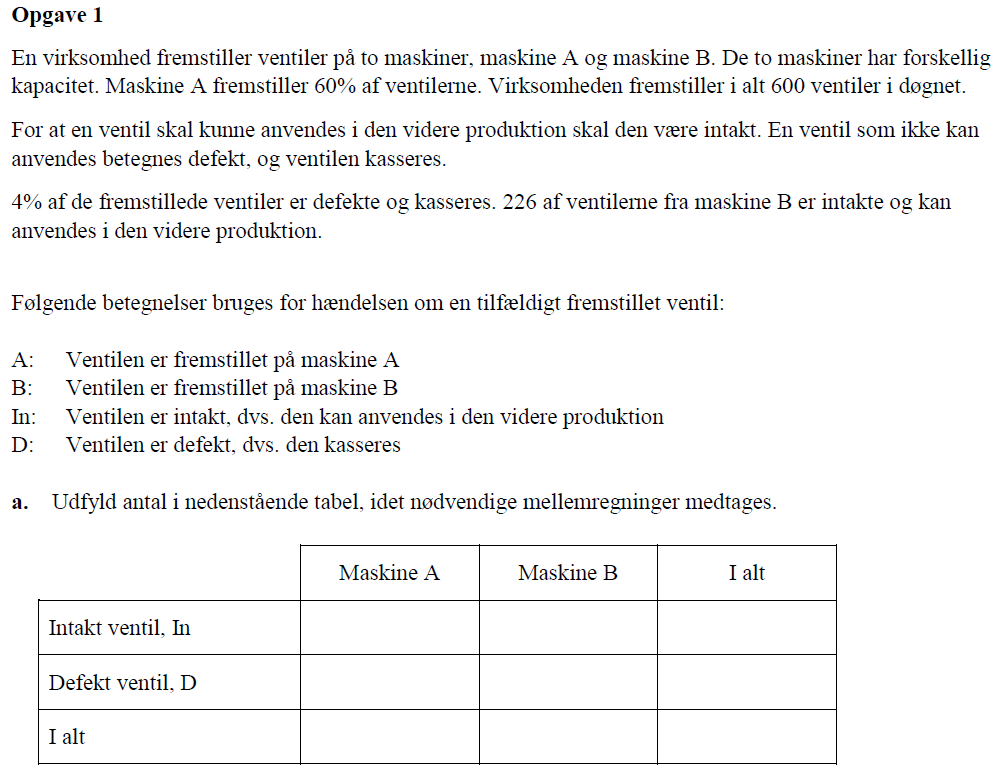

tot = 600

tot = 600

A_tot = 0.6 * tot

A_tot = 360


B_tot = 0.4 * tot

B_tot = 240

B_int = 226

B_int = 226

B_def = B_tot - B_int 

B_def = 14


tot_def = 0.04 * tot

tot_def = 24


A_def = tot_def - B_def

A_def = 10

A_int = A_tot - A_def

A_int = 350


tot_int = A_int + B_int

tot_int = 576


Kol_names = {'Maskine A', ' Maskine B', 'I alt'};
row_names = {'Int - intakt', 'Def - defekt', 'I alt'};
table([A_int; A_def; A_tot], [B_int; B_def; B_tot], [tot_int; tot_def; tot], VariableNames=Kol_names, RowNames=row_names)

ans = 3×3 table
                    Maskine A     Maskine B    I alt
                    _________    __________    _____

    Int - intakt       350          226         576 
    Def - defekt        10           14          24 
    I alt              360          240         600 


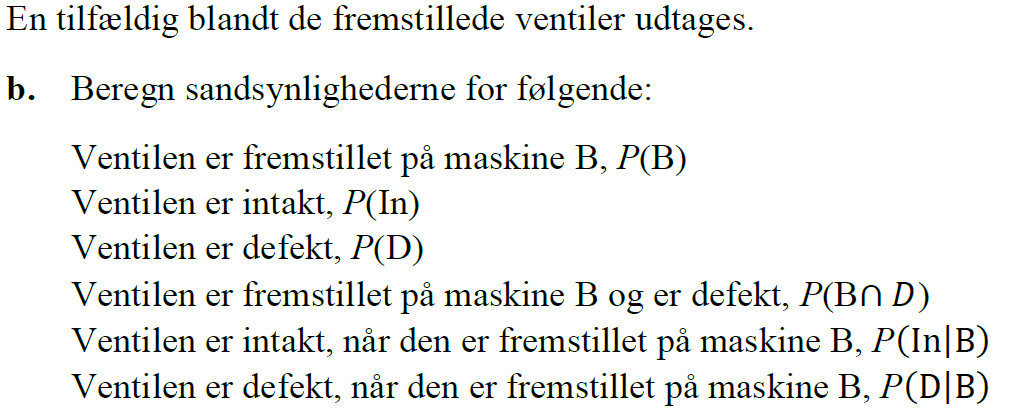

P_B = B_tot/tot

P_B = 0.4000

P_int = tot_int/tot

P_int = 0.9600

P_def = tot_def/tot

P_def = 0.0400

P_B_fel_int = B_def / tot

P_B_fel_int = 0.0233

P_int_giv_B = B_int/B_tot

P_int_giv_B = 0.9417

P_def_giv_B = 1 - P_int_giv_B % eller P_def_giv_B = B_def / B_tot

P_def_giv_B = 0.0583

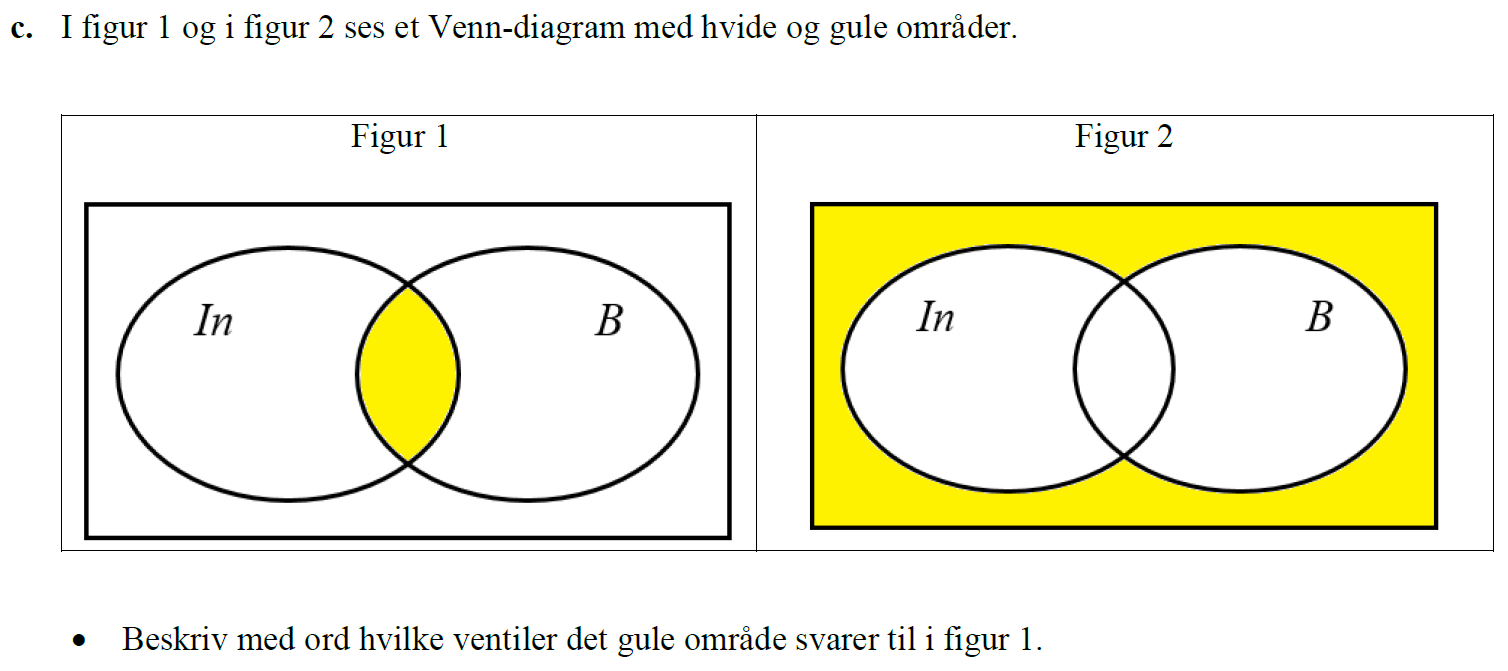

Det svare til mængden af intakte ventiler som maskine B laver.

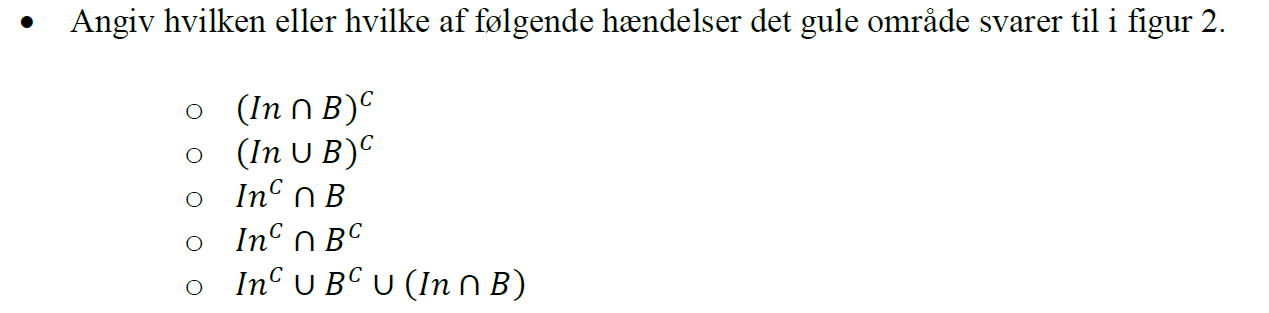

Dette svare til $(In \cap B)^C$ og $In^C \cap B^C$

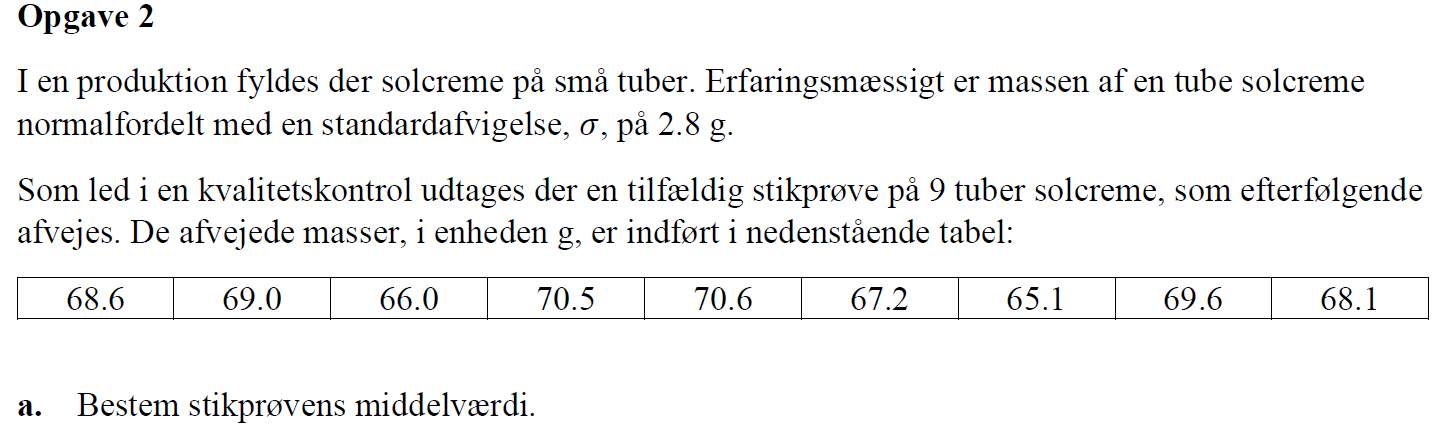

clear all
clf
format shortg
data = xlsread("Statestik\Eksamens sæt\22E\Data_M4STI1_2022E.xlsx"); %indlæser vores data
sol_data = data(1:9,1);
std = 2.8; %g

y_bar = mean(sol_data)

y_bar =          68.3


Det ses at stikprøven er en 2 sidet fordeling og vi kender spredningen derfor vælges en Z fordeling.

n = length(sol_data)

n =      9


z_a_2 = norminv(1-0.025)

z_a_2 =          1.96


konf_95 = z_a_2 * std / sqrt(n)

konf_95 =        1.8293


[y_bar-konf_95 , y_bar + konf_95]

ans =        66.471       70.129


Den beskriver at middelværdien af stik prøven($\bar y \pm2.15\ g$) ligger inden for 2,15 gram af populationens middelværdi 

Et 95%-konfidensinterval for middelværdien angiver det interval, hvor vi med 95% sikkerhed finder populationens middelværdi.

Vi prøver os frem med forskellige værdier

syms n_test

eq = 1.5 == z_a_2 * std / sqrt(n_test);
sol = solve(eq, n_test);
vpa(sol,4)

$$ans = 13.39$$

Således skal der være en stikprøvestørrelse på 14

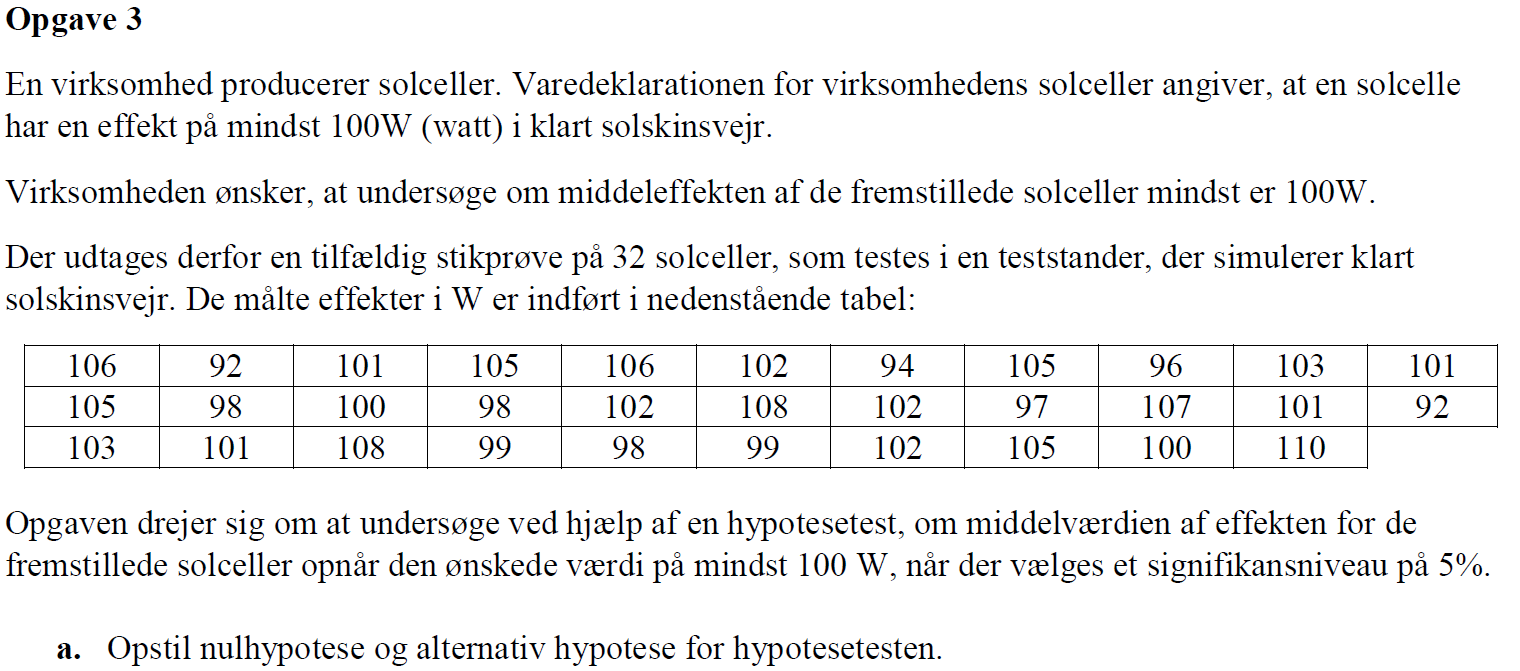

clear all
clf
format shortg
data = xlsread("Statestik\Eksamens sæt\22E\Data_M4STI1_2022E.xlsx"); %indlæser vores data
sol_celle_data = data(:,4);
mu = 100; %W
n = length(sol_celle_data)

n =     32



$$H_0:\ \mu  = 100\ W \\
H_a:\ \mu < 100\ W$$


Hvis middelværdien er ens med middelværdien af populationen kan vi ikke forkaste vores hypotese. det bemærkes at testen er 1 sidet

**b. Opstil en formel for teststørrelsen (teststatistikken), og angiv hvilken fordeling den følger.**

Der benyttes en t fordeling da vi har en stikprøve på en lille til mellem størrelse og vi ikke kender variansen. 

Dermed benyttes ligningen for teststørrelsen som:

**c. Bestem den kritiske værdi og angiv det kritiske område for testen.**

df = n -1;
alpha = 0.05 % da testen er 1 sidet

alpha =          0.05


t_c = tinv(0.05, df) 

t_c =       -1.6955


**d. Beregn teststørrelsens (teststatistikkens) værdi, idet nødvendige mellemregninger medtages.**

y_bar = mean(sol_celle_data)

y_bar =        101.44


var = var(sol_celle_data)

var =        20.125


s = std(sol_celle_data)

s =        4.4861


t_0 = (y_bar - mu) / (s/sqrt(n))

t_0 =        1.8127


**e. Konkluder på hypotesetesten.**


$$t_0 < t_c$$


t_0 > t_c

ans = logical
   1


Det ses således at $t_0(1,81)$ er mindre end $t_c(-1,70)$ og vi er således ikke ude i det kritiske område. Dermed kan vi ikke forkaste vore $H_0$ hypotese

**f. Hvilken antagelse er der foretaget for at udføre hypotesetesten?**

**Er antagelsen rimelig?**

Det er antaget at populationen er normalt fordelt og at vores stikprøve er repressentativ for populationen. Her er brugt den centrale grænseværdisætning da stikprøvestørrelsen er størrer end 30

**g. Lav et boxplot, et histogram og et normalfordelingsplot for de målte data.**

**Kommenter de tre plots.**

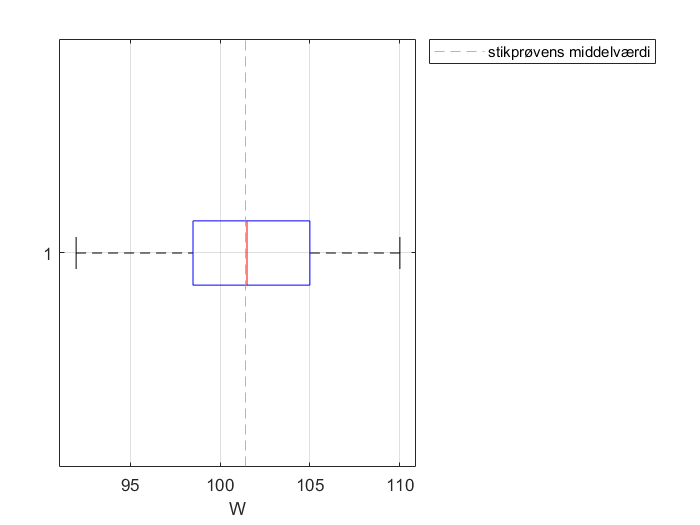

figure(1)
X = sol_celle_data;
md = median(X); % finder medianen
q1 = prctile(X, 25); % finder første kvatil ved at finde data punkt ved 25%
q3 = prctile(X, 75); % finder første kvatil ved at finde data punkt ved 75%
Q = prctile(X, [25, 50, 75]); % finder alle 3 kvatiler ud fra 25% 50% 75% Q2 = medianen
Q = quantile(X, 3); % finder alle 3 kvatiler ud fra procent

boxplot(X,'Orientation',"horizontal")
xline(y_bar, '--', color='g', DisplayName='stikprøvens middelværdi')
xlabel('W')
legend('location', 'northeastoutside')
grid("on")

Boxplottet har en median på 101.5, som stort set er sammenfaldende med middelværdien på 101.4.

Det interkvartile range ligger pænt symmetrisk omkring medianen. Med nedre kvartil på 98.5 og øvre kvartil på 105.0. Den øvre del er lidt bredere end den nedre del.

Den nedre kost er lidt længere end den øvre. Dvs. fordelingen af data er lidt venstre skæv.

Der er ingen outliers.

Dvs. data kommer fra en stort set pæn fordeling

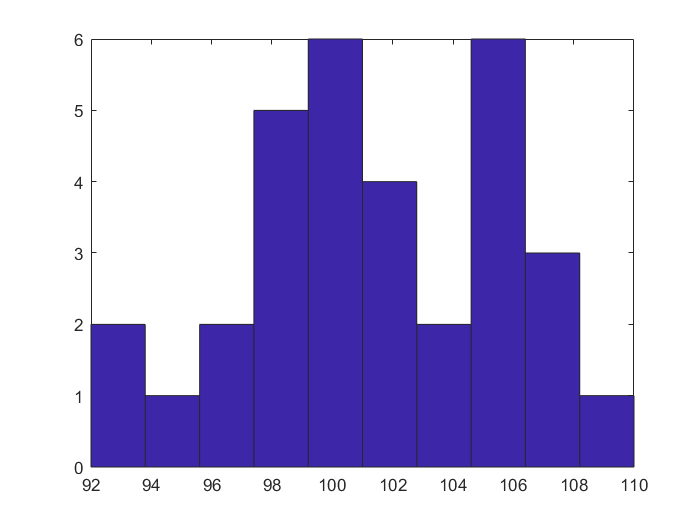

figure(2)
hist(sol_celle_data,10)

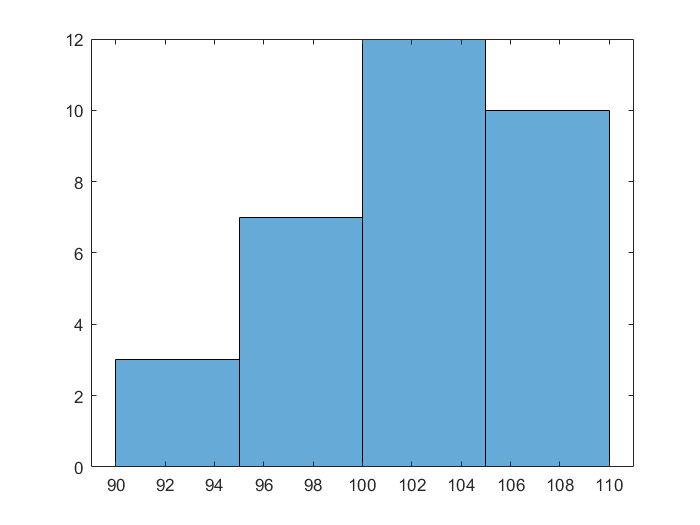

histogram(sol_celle_data, [90:5:110])

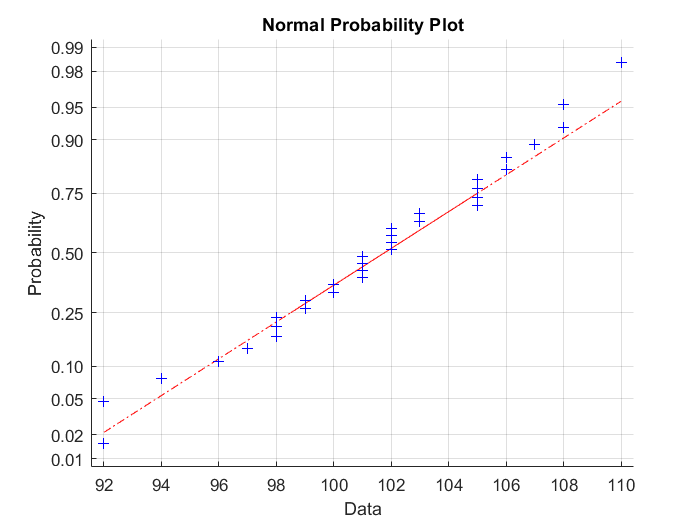

figure(3)
normplot(sol_celle_data)

Samlede set ligger vores middelværdi pænt i quitil 2 har en fin histogram form dog med nogle afvigelser omkring 104. Normalplottet sølger en find fordeling der måske er meget lidt skæv i toppen. alt i alt er det en fin model.

Boxplot, histogram og normalfordelingsplot viser alle, at stikprøven kommer fra en pæn fordeling, der godt kunne ligne en normalfordeling. Så også her er kravet for at den centrale græseværdi sætning gælder,opfyldt.

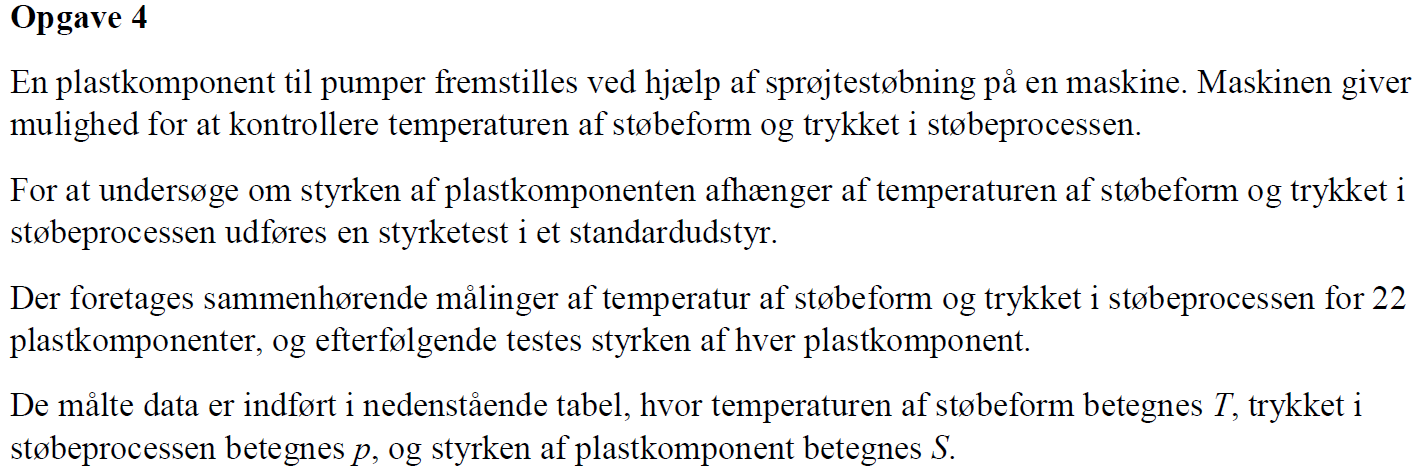

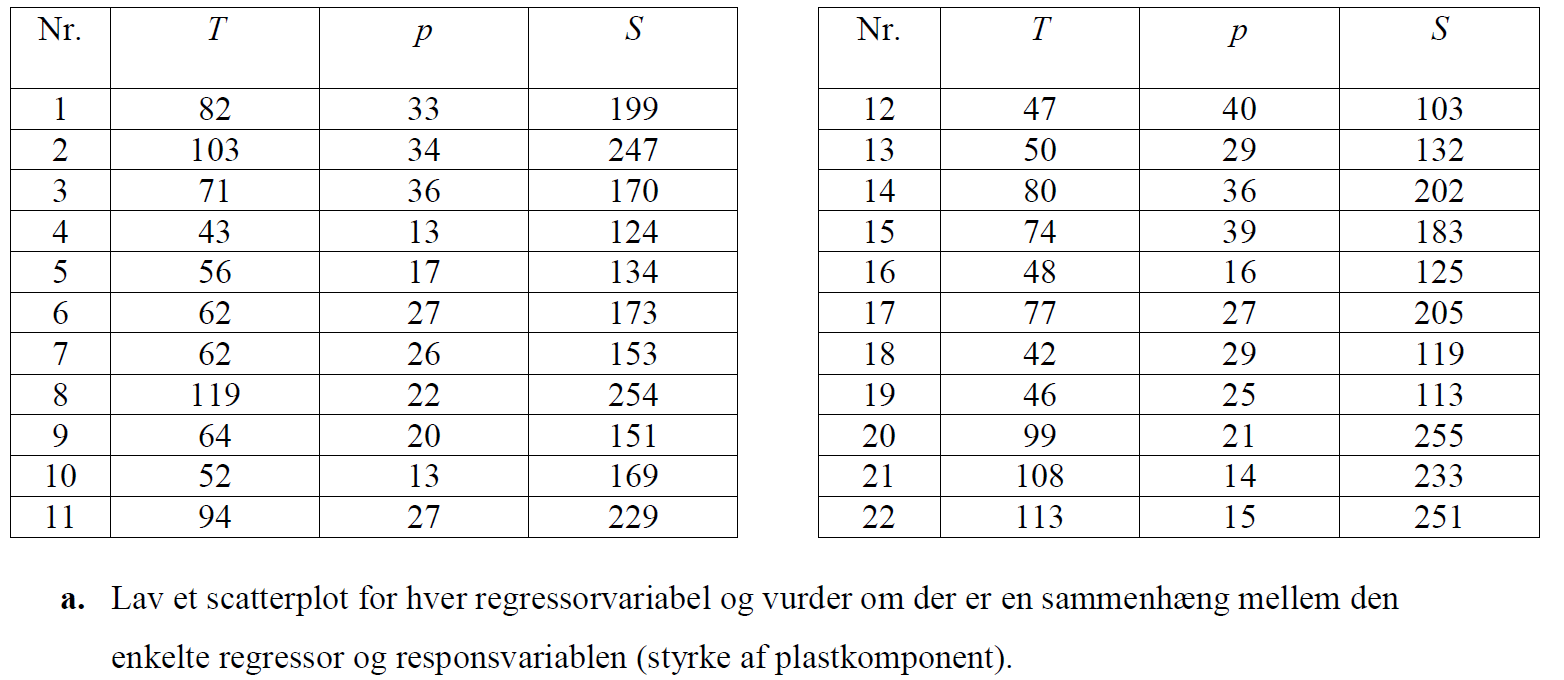

b. Lav en multipel lineær regressionsanalyse, der beskriver styrke af plastkomponent (S) som funktion af temperatur af støbeform (T) og af trykket i støbeprocessen (p). Opskriv regressionsligningen.

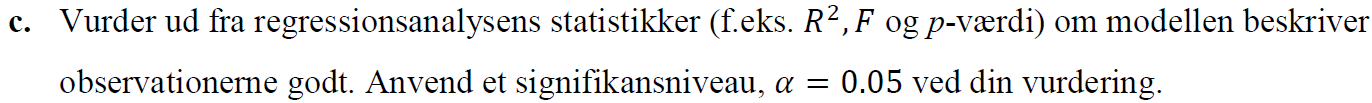

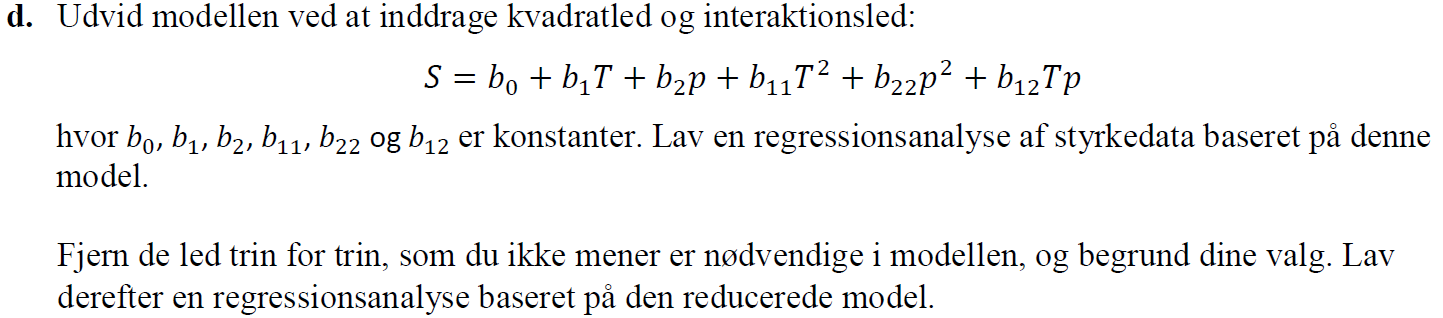

e. Opskriv ligningen for din foretrukne model.

f. Undersøg om der er ”unormale” datapunkter, dvs. løftestangspunkter, outliers, indflydelsespunkter. Svaret skal begrundes.